# EE-266 - Identificação e Filtragem

### Questão 4, P2 (Entregas Parciais)

#### Profª Gabriela Werner Gabriel

#### Jian Lucas Brito Veras

#### 2021.2

A presente questão buscou desenvolver um filtro de Kalman para o sistema com estados de posição-velocidade-aceleração do tipo $\xi=[x \text{ } y \text{ } \dot{x} \text{ } \dot{y} \text{ } \ddot{x} \text{ } \ddot{y}]'$ e com representação no espaço de estados na forma


$$\dot{\xi} = F \xi + Gq\\
y=H\xi+r$$


Sendo $q
$ e $r$ ruídos brancos de média nula, $R,Q$ suas respectivas matrizes de correlação. O sistema, dado originalmente em tempo contínuo

Tem-se que ruídos e estado são descorrelacionados entre si, aposição inicial é certa e diferente de zero, com velocidades e acelerações iniciais nulas. Dessa forma, tem-se que as condições gaussianas lineares são adequadamente atendidas.

A matriz $G$ é facilmente determinada, uma vez que o ruído $q$ é descorrelacionado, de modo que sua matriz de corrleação é a identidade. Dessa forma


$$GG'= \pmatrix{0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 10^{-6} & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 10^{-6} \cr }\\

$$



$$G= \pmatrix{0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & 0 & 10^{-3} & 0 \cr
0 & 0 & 0 & 0 & 0 & 0 & 10^{-3} \cr }\\


$$


De início, faz-se a declaração das matrizes que descrevem o sistema. Vale ressaltar que o sinal de controle é nulo.

*Comentário: entendendo que o sistema foi dado em tempo contínuo, tentei fazer a discretização t.q. visto em EES-20, utilizando a função c2d(sys,0.1,'zoh'). Todavia obtive erro, informando que deveria ser feito um processo d2d. Compreendi assim que o uso de ss(.) me forneceu um sistema já discretizado. Não consegui, portanto, produzir gráficos de posição e velocidade, os quais também não foram requeridos (tinham finalidade apenas de observação). Todavia, os gráficos de P foram obtidos com sucesso, atendendo a demanda do problema.*

clear all;
close all;

F = zeros(6); F(1,3) = 1; F(2,4) = 1; F(3,5) = 1; F(4,6) = 1;
GQGt = zeros(6); GQGt(5,5) = 1e-6; GQGt(6,6) = 1e-6;
G = GQGt*1e+3;
Q=eye(6);
H = zeros(2,6); H(1,1) = 1; H(2,2) = 1;
R = [1 0;0 1];


SYS = ss(F,G*chol(Q),H,0,1);
Observabilidade = gram(SYS,'o')

Observabilidade =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Controlabilidade = gram(SYS,'c')

Controlabilidade = 	1.0e+-6 *

    1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


Sendo as matrizes de controlabilidade e de observabilidade invertíveis, conforme visto acima, tem-se que, com o processo de detemrinação do filtro, a variância  $P(k+1|k)$ tenderá ao *estado estacionário* e a resolução da equação de Riccati na detemrijnação da variância será única.

loops =50;
xi{1} = [0 0 0 0 0 0]'; % Posição inicial (x,y) certa, com velocidades e acelerações nulas
posx(1)=xi{1}(1); posy(1)=xi{1}(2);
xia{1} = zeros(6,1); Pa{1} = zeros(6); % Inicialização dos estimadores

Para melhor entendimento, esclarece-se a notação utilizada no código:


$$
xip \Rightarrow \hat{\xi}(k+1|k): \text{ $\xi$ predito}\\
xia \rightarrow \hat{\xi}(k|k): \text{ $\xi$ atualizado}\\
yp \Rightarrow \hat{y}(k+1|k): \text{ $y$ predito}\\
ya \rightarrow \hat{y}(k|k): \text{ $y$ atualizado}\\
Pp \Rightarrow P(k+1|k): \text{ $P$ predito}\\
Pa \rightarrow P(k|k)/P(k+1|k+1): \text{ $P$ atualizado}\\
$$


Enfim, parte-se para a construção propriamente dita do filtro.

for k=1:loops
    % Dinâmica do Sistema
    q = sqrt(Q)*randn(6,1);
    r = sqrt(R)*randn(2,1);
    xi{k+1} = F*xi{k} + G*q;
    posx(k+1) = xi{k+1}(1);
    posy(k+1) = xi{k+1}(2);
    y{k+1} = H*xi{k+1} + r;
    
    % Predição (1 passo à frente)
    xip{k+1} = F*xia{k};
    xpred(k+1) = xip{k+1}(1);
    ypred(k+1) = xip{k+1}(2);
    yp{k+1} = H*xip{k+1};
    
    % Inovação da medida
    nu = y{k+1} - yp{k+1};
    
    % Variâncias associadas às Predições e à Inovação
    Pp{k+1} = F*Pa{k}*F' + GQGt;
    Ppred(k+1)=trace(Pp{k+1});
    S = R + H*Pp{k+1}*H';
    
    % Cálculo do Ganho do Filtro
    W = Pp{k+1}*H'/S;
    
    % Atualizações do Estado e da Variância
    xia{k+1} = xip{k+1} + W*nu;
    xatual(k+1) = xia{k+1}(1);
    yatual(k+1) = xia{k+1}(2);
    Pa{k+1} = Pp{k+1} - W*S*W';
    Patual(k+1)=trace(Pa{k+1});
end

A segir, faz-se a preparação da apresentação dos dados. Além das informações $P(k+1|k), P(k|k) \text{ e } P(\infty)$, produziu-se um gráfico comparando a posição, isto é, as coordenaadas $(x,y)$.

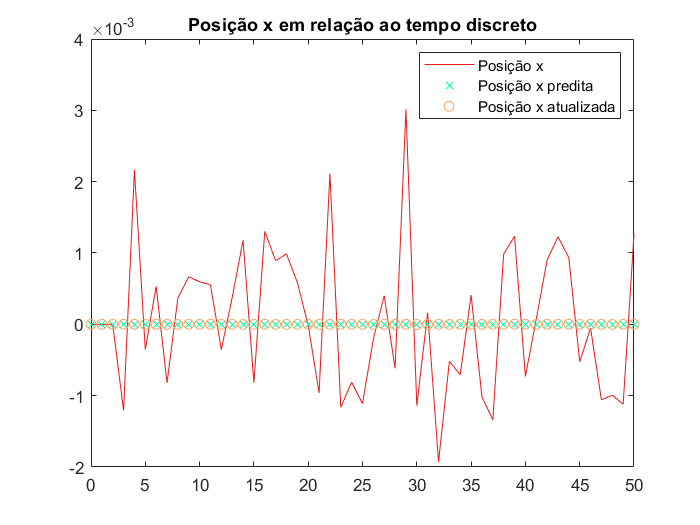

% Determinação de P(infty) a aprtir da função idare, que resolve a equação
% de Riccati
[Pric,~,~] = idare(F',H',GQGt,R,zeros(6,2),eye(6));

figure()
plot(0:loops,posx,'Color',[0.9 0.1 0.1]); hold on
plot(0:loops,xpred,'Color',[0/255 250/255 154/255],'Marker','x','LineStyle','none');
plot(0:loops,xatual,'Color',[244/255 164/255 96/255],'Marker','o','LineStyle','none'); hold off
title('Posição x em relação ao tempo discreto')
legend('Posição x','Posição x predita','Posição x atualizada')

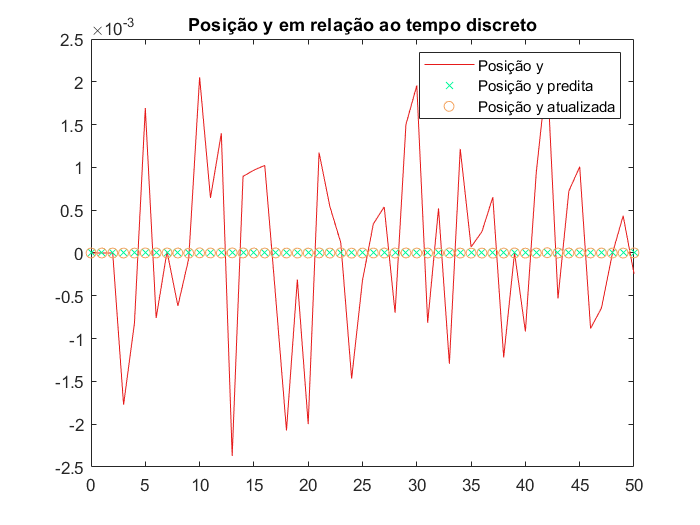

figure()
plot(0:loops,posy,'Color',[0.9 0.1 0.1]); hold on
plot(0:loops,ypred,'Color',[0/255 250/255 154/255],'Marker','x','LineStyle','none');
plot(0:loops,yatual,'Color',[244/255 164/255 96/255],'Marker','o','LineStyle','none'); hold off
title('Posição y em relação ao tempo discreto')
legend('Posição y','Posição y predita','Posição y atualizada')

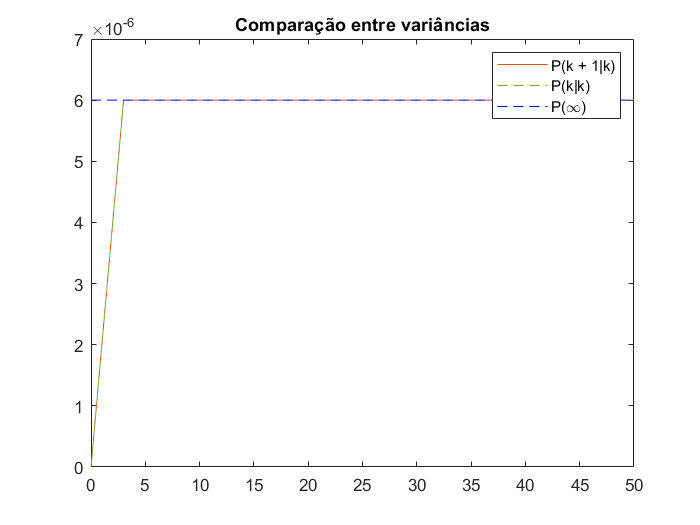

figure()
plot(0:loops,Ppred,'Color',[0.8500 0.3250 0.0980]); hold on
plot(0:loops,Patual,'--','Color',[0.4660 0.6740 0.1880]);
plot(0:loops,ones(loops+1)*trace(Pric),'b--'); hold off
title('Comparação entre variâncias')
legend('P(k + 1|k)','P(k|k)','P(\infty)')

O gráfico comparativo das variâncias confirma o previsto teoricamente discutido ao início da resolução, uando se discutiram as observabilidade e controlabilidade do sistema. A variância $P(k+1|k)$, juntamente à variância $P(k|k)$, tendeu com poucas iterações ao valor de $P(\infty)$, este obtido com a resolução direta da equação linear de Riccati pela função *idare.*